clc;clearvars;close all;
global DOFS;
DOFS = [true,true,true];
L = 100;
E = 2e4;
I2 = 131.1417;
I1 = 677.5317;
A2 = 7.7; A1 = 15.52;
Aeq2 = 2.8356;
Aeq1 = 6.0623;
v = 0.3;
p = 20;
n1 = NODES(1,0  ,0,"constraint" ,"fixed");
n2 = NODES(2,L  ,0,fy=-7.5*p,m=-p*L);
n3 = NODES(3,2*L,-3*L/4,constraint = "fixed",dy=-0.01*L,dRz = -deg2rad(2));
cr1 = tempcross(E,A1,I=I1,Aeq=Aeq1);
cr2 = tempcross(E,A2,I=I2,Aeq=Aeq2);
m1 = member(n1,n2,cr1);
m2 = member(n2,n3,cr2);
L1 = rec(m1,0,L,9*p/L,"down","g");
L2 = con_fm(m2,0.5*m2.L,6*p,"down","g");

## Automatically creating the cell matrices and running the final solver

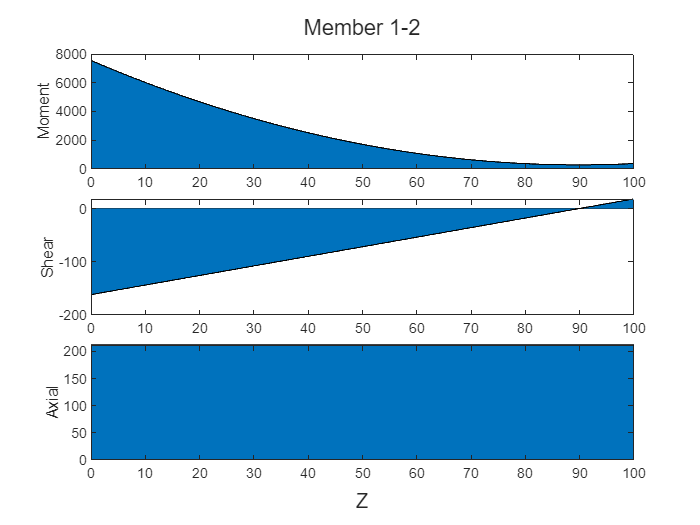

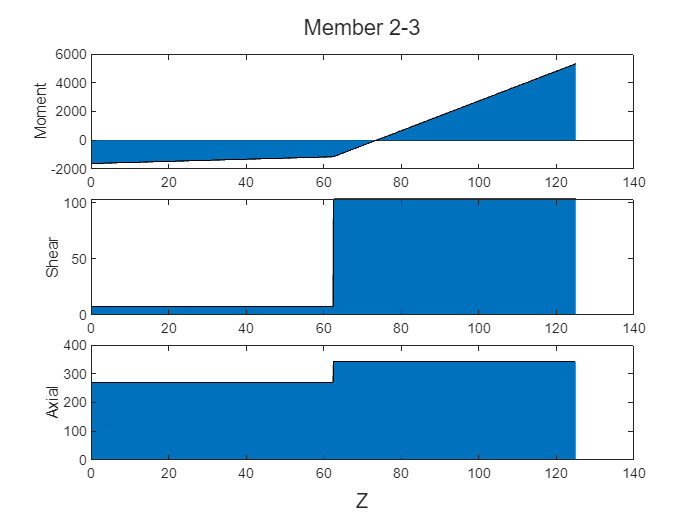

Deflections:
   -0.0682
   -1.5054
   -0.0182

Reactions:
   1.0e+03 *

    0.2118
    0.1618
    7.5546
   -0.2118
    0.2882
   -5.3216




members = {};
nodes = {};
loads = {};
j = evalin('base','who');
for n = 1:length(j)
    r = evalin('base',j{n});
    if isa(r,'member')
        members = {members{:},r};
    elseif isa(r,'NODES')
        nodes = {nodes{:},r};
    elseif isa(r,'con_fm')||isa(r,'con_m')||isa(r,'n_tri')||isa(r,'rec')||isa(r,'rev_tri')
        loads = {loads{:},r};
    end
end
[Ar,D,Df,members] = final_solver(members,nodes,loads);